# Script for Fitting Experimental Data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

format shortG

%%%%%%%%% Experimental Data %%%%%%%%%
% Parameter selection input
param_selection = [true; %\ alpha_P - production rate of protein
    false; % alpha_M - production cost of mRNA
    true; % alpha_E - production cost of resources
    true; % delta_P - degradation rate of protein
    false; % delta_M - degradation rate of mRNA
    true; % delta_E - degradation rate of resources
    false; % r_P - recycle of protein into resource
    false; % r_M - recycle of mRNA into resource
    ];
% scale_limits = [4 4; 
%     -3 -2;
%     -3 -2;
%     -6 -5;
%     -4 -3;
%     -4 -3;
%     -12 -11;]; % scale limits for the active parameters in order of appearance/ to initiate the values, we first look at the best order of magnitude to work on with each parameters
scale_limits = [4 4; 
    -3 -2;
    -4 -2;
    -6 -5; %%%%
    -12 -3;
    -4 -3;
    -12 -10;
    -12 -2];
% Data input - input your data here
time_points = [5 10 15 20 30 45 60];
% file_name = "data-04-24-2019";
% time_points = [45,60,90,120,150]-35;
file_name = "Plasmodium Dataset";
% No pre-incubation data
data_points_no_inc = [134814.2,535553.5,1117699.167,2765650,4676896.667,5991675;
    985829.5,3611828.333,5887583.333,11820630,17519766.67,18695350;
    2096233.333,6740431.667,10085211.67,16204400,20418983.33,22835683.33;
    2372001.66,7418885,10977265,1.70E+07,2.34E+07,2.64E+07;
    2586933.333,8796735,11737600,15891683.33,21423866.67,21460700;
    2641990,7746235,10666288.33,14212783.33,18956433.33,20052250;
    2803356.667,8146876.667,10604476.67,1.60E+07,1.76E+07,1.41E+07];
% 
% data_points_no_inc = [31081.61667,80876.33333,116425,199506.8333,393907.5,730762.3333;
%     47467.83333,142514.1667,223320.1667,424508.8333,887579.8333,1605118.333;
%     58311.1,193246.5,314717.6667,709548.6667,1643731.667,3275698.333;
%     61394.15,194404.5,341728.3333,780483,2058018.333,4467783.333;
%     57774.4,192915,328558.8333,789057.5,1986131.667,4640705];

% %human\
% data_points_no_inc = [13360.52667,26278.82333,82772.5,287379.35,1305722.333,5027223.333;
%     65216.15,353086.8333,1332983.333,3802020,6410328.333,9424560;
%     92379.71667,653278.8333,2585690,6707230,9687645,11979583.33;
%     117113.2667,704809,2730830,6838138.333,10193601.67,12878600;
%     92334.66667,680109.5,2739481.667,7069323.333,10026440,13016533.33];


protein_level_no_inc = transpose(data_points_no_inc(:,[1 2 3 4]));
concentrations_no_inc = [10 25 50 100];


% Pre-incubation data
% data_points_inc = [61178.38333,165426.3333,45311.63333,185069;
%     88255.15,307826.6667,69455.95,312446.8333;
%     98001.66667,455530.5,81043.03333,436292.1667;
%     102727.8333,479963.6667,82493.28333,467082.6667;
%     92647.28333,467688.2,74704.38333,449602.3333];

data_points_inc = [195026.8333,1930060,128436.5,1866635,100820.2833,1788838.333;
    1038039.167,7076921.667,674758.8333,5255980,502054.1667,4151856.667;
    1648073.333,8311923.333,964648.1667,6081458.333,839117.5,5086518.333;
    1953148.333,9172461.667,1170175.333,6040480,1042688,5222341.667;
    2027258.333,8611016.667,1418876.667,6075821.667,1382448.333,5697188.333;
    2154196.667,7409325,1539318.333,5770991.667,1618433.333,5651486.667;
    2106806.667,6635273.333,1543413.333,5019161.667,1616306.667,5102551.667;];

%human
% data_points_inc = [3376.965,78194.06667,547.2648333,48271.33333;
% 10645.95667,413853.5,3146.668333,170006.3333;
% 14418.48333,633987.1667,5371.008333,274315.1667;
% 17159.78333,696276.5,8050.38,324035.5;
% 19304.88333,718321.1667,11157.77833,343845.3333];




protein_level_inc = transpose(data_points_inc);
concentrations_inc = [10 50 10 50 10 50];
preincubation_times_inc = [15 15 30 30];
% preincubation_times_inc = [6 6 12 12];

choose_inc = [1 2 3 4];
protein_level_inc = protein_level_inc(choose_inc,:);
concentrations_inc = concentrations_inc(choose_inc);
preincubation_times_inc = preincubation_times_inc(choose_inc);
%%%%%%%%%%%%%%%%%%%%%%%%%
% data_points_no_inc_temp = [18.58333333,37.30566667,16.80556667,19.11111667,18.66668333,22.55558333;
%     6092.51,11866.83333,17955.45,25277.35,58329.06667,143137.3333;
%     31081.61667,80876.33333,116425,199506.8333,393907.5,730762.3333;
%     47467.83333,142514.1667,223320.1667,424508.8333,887579.8333,1605118.333;
%     58311.1,193246.5,314717.6667,709548.6667,1643731.667,3275698.333;
%     61394.15,194404.5,341728.3333,780483,2058018.333,4467783.333;
%     57774.4,192915,328558.8333,789057.5,1986131.667,4640705]; %P.F
% 
% data_points_inc_temp = [23.0278,20.94446667,20.0278,20.8889;
%     17815.31667,24768.45,11197.47667,30144.08333;
%     61178.38333,165426.3333,45311.63333,185069;
%     88255.15,307826.6667,69455.95,312446.8333;
%     98001.66667,455530.5,81043.03333,436292.1667;
%     102727.8333,479963.6667,82493.28333,467082.6667;
%     92647.28333,467688.2,74704.38333,449602.3333]; %P.F
% time_points_temp = [15,30,45,60,90,120,150];

%%%%change%%%%
loss_scale = time_points .^-0.2;
loss_scale = length(loss_scale)*loss_scale/sum(loss_scale);
% loss_scale = ones(1, length(time_points));


%%%%%%%%% Auxiliary setup %%%%%%%%% 
% These routines are setup for model fitting - don't change unless necessary
% General Input
n = sum(param_selection); % number of active parameters
preincubation_times_no_inc = zeros(1, length(concentrations_no_inc));
protein_level = [protein_level_no_inc; protein_level_inc];
concentrations = [concentrations_no_inc concentrations_inc];
preincubation_times = [preincubation_times_no_inc preincubation_times_inc];
param_selection = transpose(param_selection);

% Nelder-Mead Parameters
Nb_step = 1000;
neld_param = [1 0.5 2 0.5];
%neld_param = [1 2 0.5 0.5];

% Simulation Parameters (Runge Kutta)
% time_points = [45,60,90,120,150];
TIME = ceil(max(time_points)/10)*10;  % Time of simulation (in min)
deltat = 0.1; % Numerical time step (min)

Starting IVT model fit with following parameters turned on:
    "a_P"    "a_R"    "d_P"    "d_R"

Scale found:
        10000        0.001       0.0001        1e-06

Starting Nelder-Mead method with 1000 steps. 
Progress: 10% (step 100) 
        17223   0.00019838     0.054863   0.00032354

Progress: 20% (step 200) 
        16730   0.00018969     0.053665    0.0003165

Progress: 30% (step 300) 
        16731   0.00018478     0.053676   0.00034672

Progress: 40% (step 400) 
        17786   0.00050142     0.012899    0.0097191

Progress: 50% (step 500) 
        18398   0.00058725     0.010961     0.010418

Progress: 60% (step 600) 
        18398   0.00058725     0.010961     0.010418

Progress: 70% (step 700) 
        18398   0.00058725     0.010961     0.010418

Progress: 80% (step 800) 
        18398   0.00058725     0.010961     0.010418

Progress: 90% (step 900) 
        18398   0.00058725     0.010961     0.010418

Progress: 100% (step 1000) 
        18398   0.00058725     0.010961  

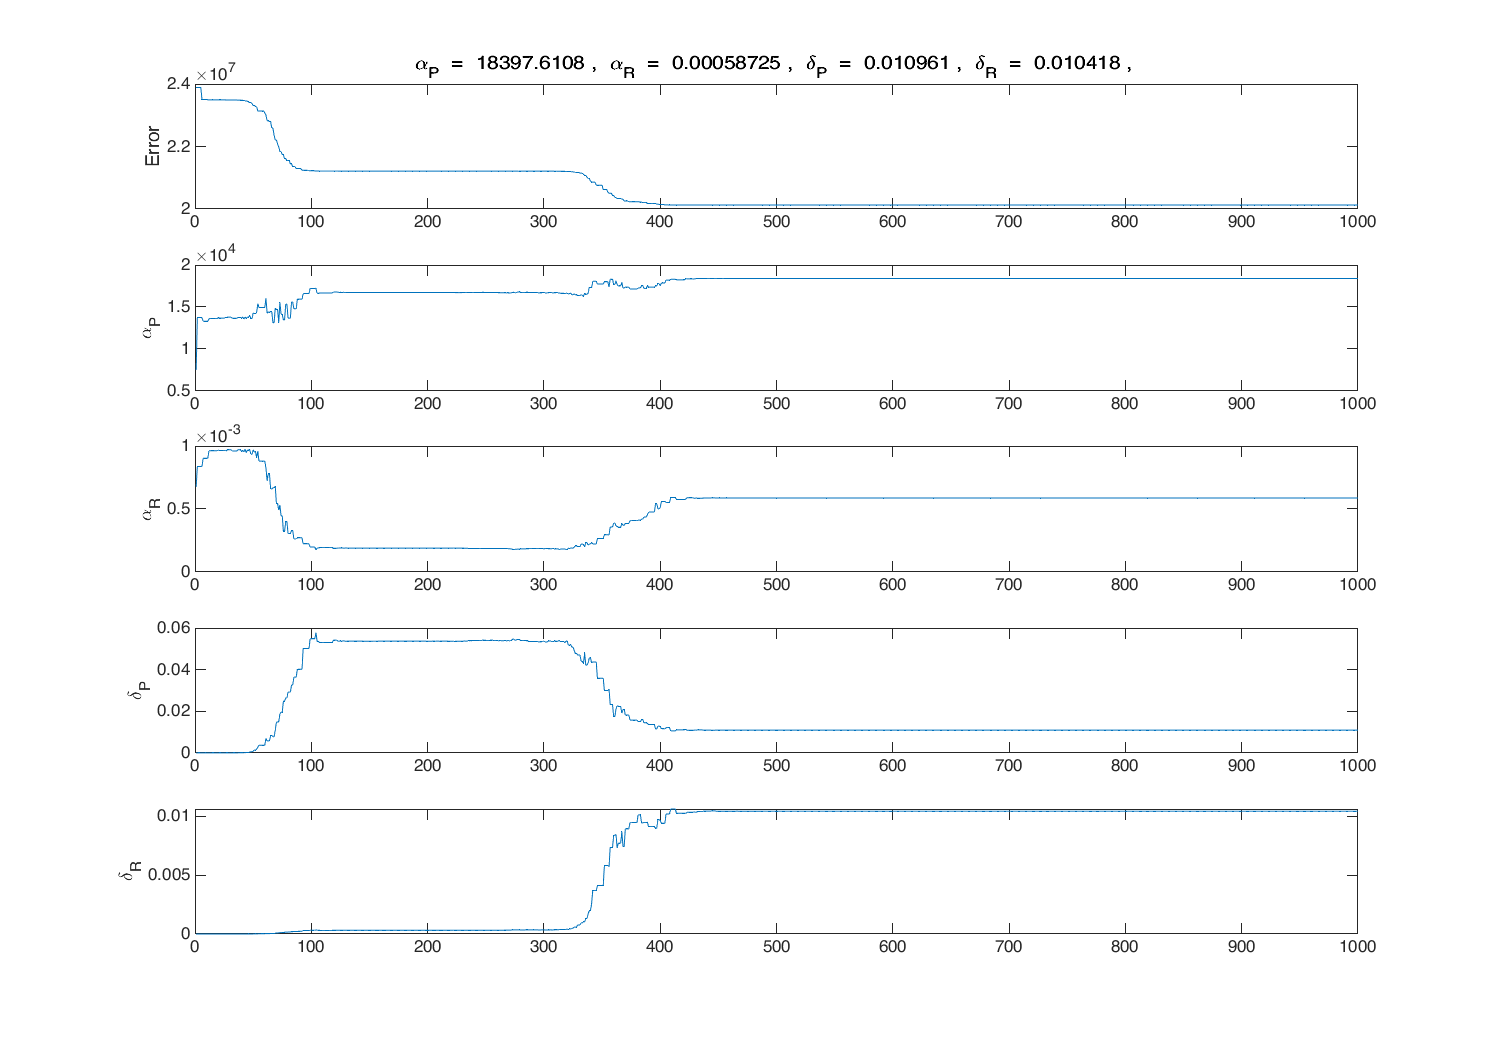

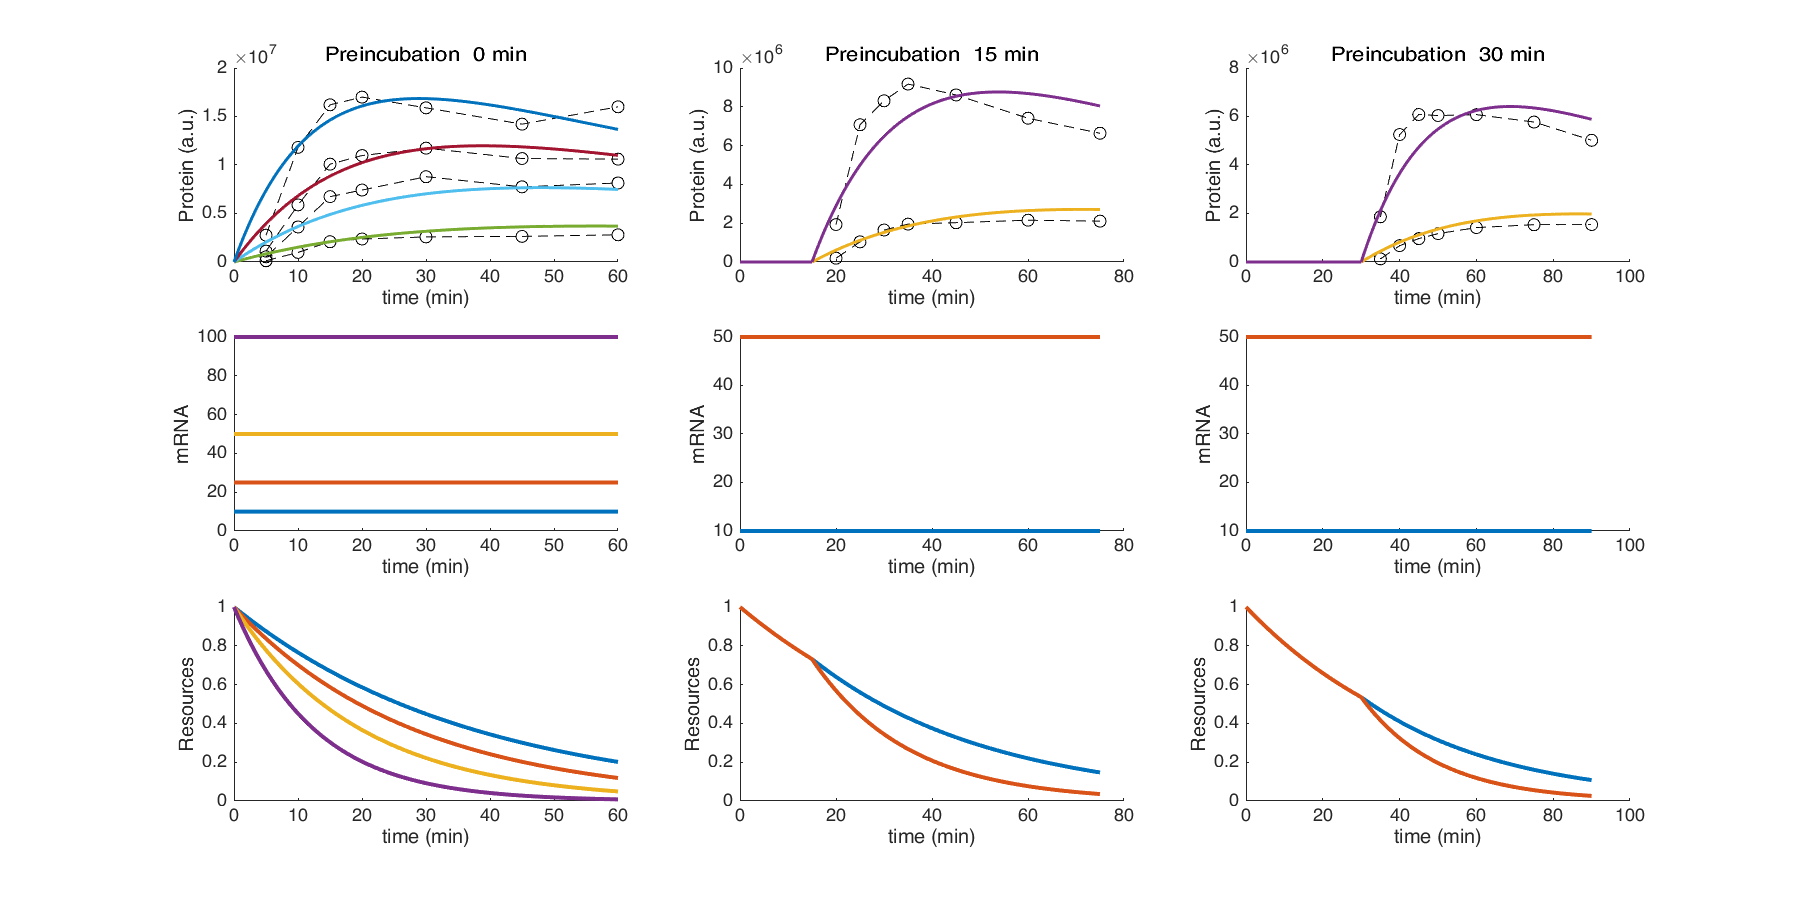

Final Parameter Values:
    "a_P"    "a_R"    "d_P"    "d_R"

        18398   0.00058725     0.010961     0.010418

Final Error:
   2.0126e+07



%%%%%%%%% Model Fit %%%%%%%%%
params = IVT_model_fit_complete(scale_limits, ...
    time_points, ...
    protein_level, ...
    concentrations, ...
    preincubation_times, ...
    n, param_selection, ...
    Nb_step, neld_param, TIME, deltat, ...
    file_name, loss_scale);

%%%%%%%%% Model Plotting %%%%%%%%%
% close;
% param_setting = [1e4 1e-3 1e-3 1e-3 1e-5 1e-3];
% disp(param_setting);
% IVT_model_fit_plot(scale_limits, time_points, protein_level, concentrations, ...
%   preincubation_times, n, param_selection, TIME, deltat, param_setting)
%%%%%%%%%%%%%%% Steady State %%%%%%%%%
%alpha_p = params(1);
% alpha_m = params(2);
% alpha_e = params(3);
% delta_p = params(4);
% delta_m = params(5);
% delta_e = params(6);
% r_p = params(7);
% betta = (r_p/delta_e - (alpha_e*delta_p)/(delta_e*alpha_p)*(-alpha_m*delta_p/(delta_m*alpha_p)));
% P_ss = delta_p/(betta*alpha_p);
% M_ss = (-alpha_m/(betta*delta_m))*(delta_p/alpha_p)^2;
% R_ss = ((r_p*delta_p/(betta*delta_e*alpha_p)) - (alpha_e/(betta*delta_e))*(delta_p/alpha_p)^2);